# Plotting Spaceships (Triangles)

We'll represent the game pieces using basic shapes, such as triangles for the spaceships, like the [space shuttle](https://en.wikipedia.org/wiki/Space_Shuttle) below.

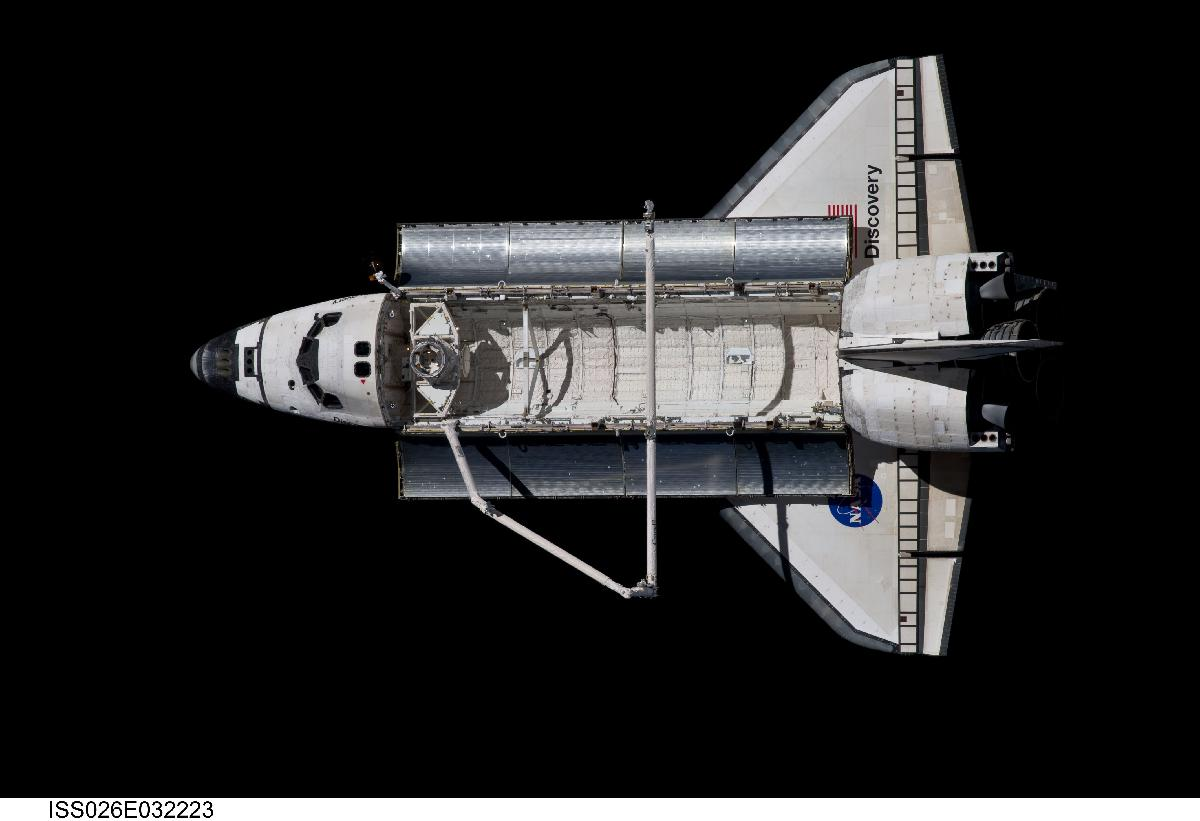     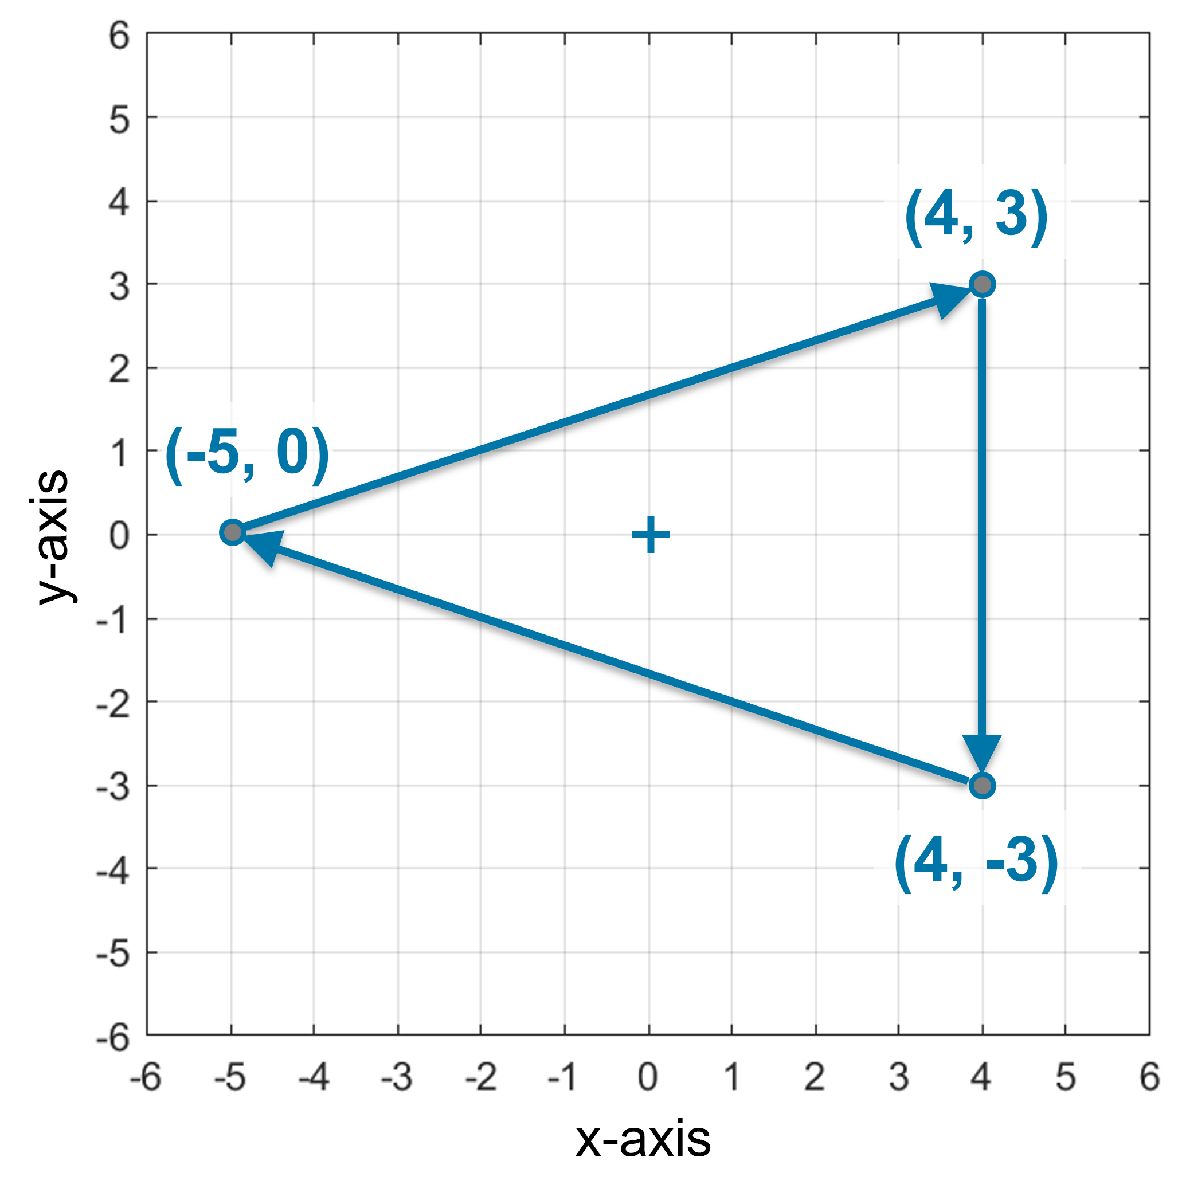

*Image Credit: *[*NASA STS-133 Space Shuttle Discovery*](https://images.nasa.gov/details-iss026e032223)

Each vertex (corner) of the triangle above is labeled with its "x" (horizontal) and "y" (vertical) locations using the notation (x, y).

## Plotting a Triangle (Task 1)

Later when we create our Astro Volley App, our plotting commands will need to specify the target axes where we want our plot to be displayed.  We’ll practice this here by getting the current axes (`ax`) and using it as the first input with all of our plotting commands below.

ax = gca;  % get current axes
cla(ax)    % clear axes

To create the triangle above we need to specify the "x" and "y" locations of the 3 vertices (corners).  To do so, we'll create one variable named `xt` to store the triangle x-values; and one named `yt` to store the triangle y-values.  

We can list the values in order by starting at the spaceship "nose" and following the arrows around the edges of the triangle.  In order to close the triangle we’ll need to return to the first point; so, we end up with 4 x-values and 4 y-values.

% TASK 1: Enter the four x and y values in the appropriate
% brackets below to create the triangle illustrated above.
xt = [ ];  % triangle x-points
yt = [ ];  % triangle y-points

% Plot x and y triangle values
plot(ax,xt,yt)

## Flipping the Ship (Task 2)

The ship above points to the left.  How can we "flip" the x-values so that it points to the right instead?  What happens when you multiply a positive number by `-1`?  What about a negative number?

To make the ship point in the opposite x-direction, all we need to do is flip the sign of the x-values such that positive values become negative, and the negative values become positive.

% TASK 2: Add a negative sign in front of xt to flip the x-direction
% of the triangle. (This is the same as multiplying xt by -1.)
plot(ax,xt,yt)

## Resizing the Ship (Tasks 3 & 4)

To make it easier to resize our ship, we’ll normalize the triangle points such that the distance from the center (0,0) to the "nose" has a value of 1 unit (instead of 5).  We can do this by simply dividing the previous `xt` and `yt` values by 5.

% TASK 3: Normalize xt and yt by dividing both by 5.
xt = [-5 4 4 -5];  % unit triangle x-points
yt = [ 0 3 -3 0];  % unit triangle y-points

We can then use the ship size parameter below (`Rs`) to scale these "unit" triangle points to re-plot our ship with a different size.  (To keep the same size ship as before we'd now just set `Rs = 5`.)

% TASK 4: Make the ship larger by changing Rs such that
% the "nose" of the ship extends to 10 (instead of 1 below).
Rs = 1;  % ship size (from center to nose)

% Plot flipped ship
plot(ax,-Rs*xt,Rs*yt)  % negative sign flips direction

Note, MATLAB automatically zooms in on the triangle so your figure may look the same at first; but notice the labels on the x-axis and y-axis are now different than before.

## Relocating the Ship (Task 5)

We can relocate our ship from (0,0) to another position by specifying the x and y values of the new location and adding these to the x and y values of the triangle.

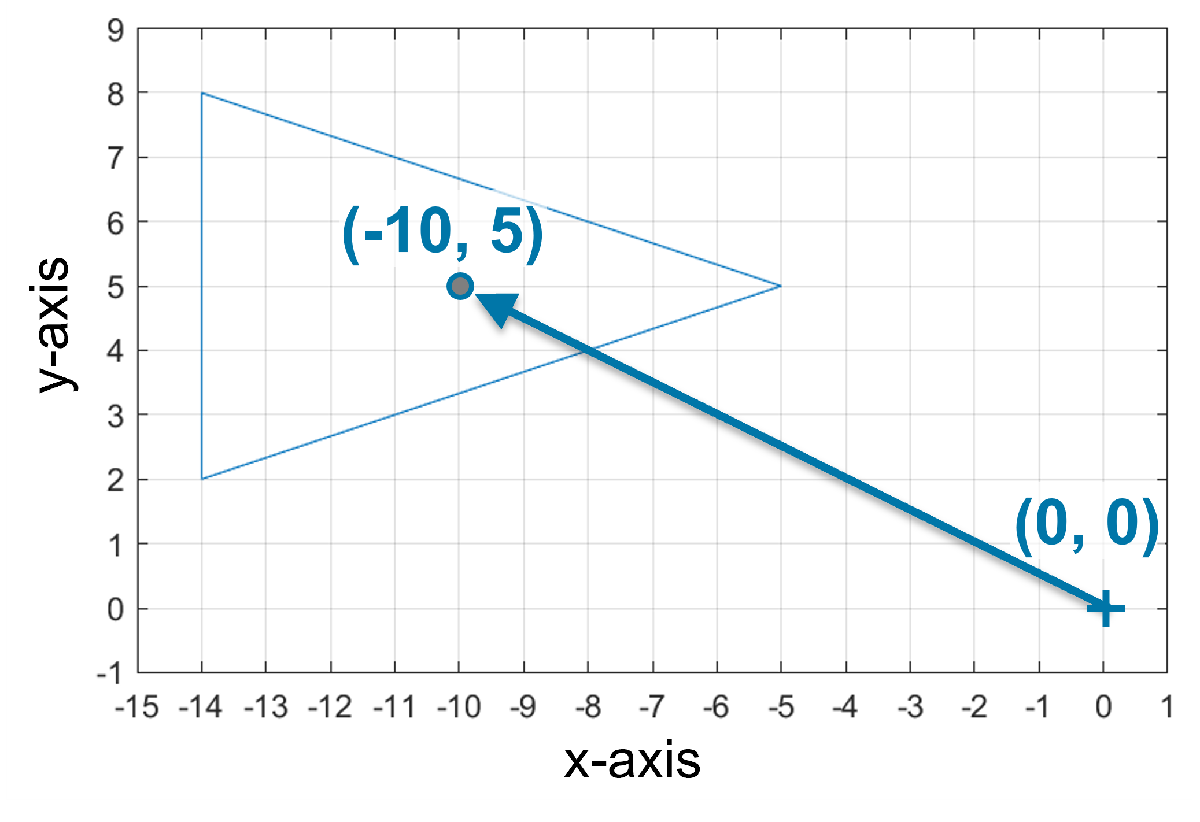

% TASK 5: Change the values of xs and ys to relocate the
% ship to the x and y location illustrated above.
xs = 0;  % ship x-position
ys = 0;  % ship y-position

% Plot relocated ship
Rs = 5;  % to be consistent with picture above
plot(ax,xs-Rs*xt,ys+Rs*yt)  % negative sign flips direction
xlim(ax,[-15 1])            % x-axis display limits [min max]
ylim(ax,[-1 9])             % y-axis display limits [min max]

This time we used the `xlim` and `ylim` functions to set the display limits on the x and y axes to match the figure above.  As such, if `xs` and `ys` are not set to match the ship position illustrated above, your ship may not be visible inside the axes limits.

## Coloring the Ship (Task 6)

We can fill our ship with color by replacing the `plot` command with the `fill` command.  To do so we'll also need to specify the desired Red-Green-Blue [(RGB) color code](https://www.rapidtables.com/web/color/RGB_Color.html#color-table), which recall is an array of 3 numbers with values between 0 and 255.

For example, [255 255 0] represent a color with full red, full green, and no blue - which creates yellow.  Note, the `fill` function expects these values to be between 0 and 1, so we divide the color array by 255.  This has already been added to the code below.

% TASK 6: Change the zeros in the color code below
% to create a blue-green ship (instead of black).
cs = [0 0 0]/255;  % ship RGB color code

% Plot ship filled with color
fill(ax,xs-Rs*xt,ys+Rs*yt,cs)  % negative sign flips direction

Notice once again that if we do not specify the x and y axes limits, MATLAB automatically zooms in on the plot; but we can still see the triangle location based on the x-axis and y-axis labels.

## Adding Another Ship (Tasks 7 & 8)

We can add a second ship by adding additional values to our variables for the ship x location (`xs`), y location (`ys`), size (`Rs`), and color code (`cs`).  We'll then use the first value of each array to plot Ship 1; and the second value of each array to plot Ship 2.

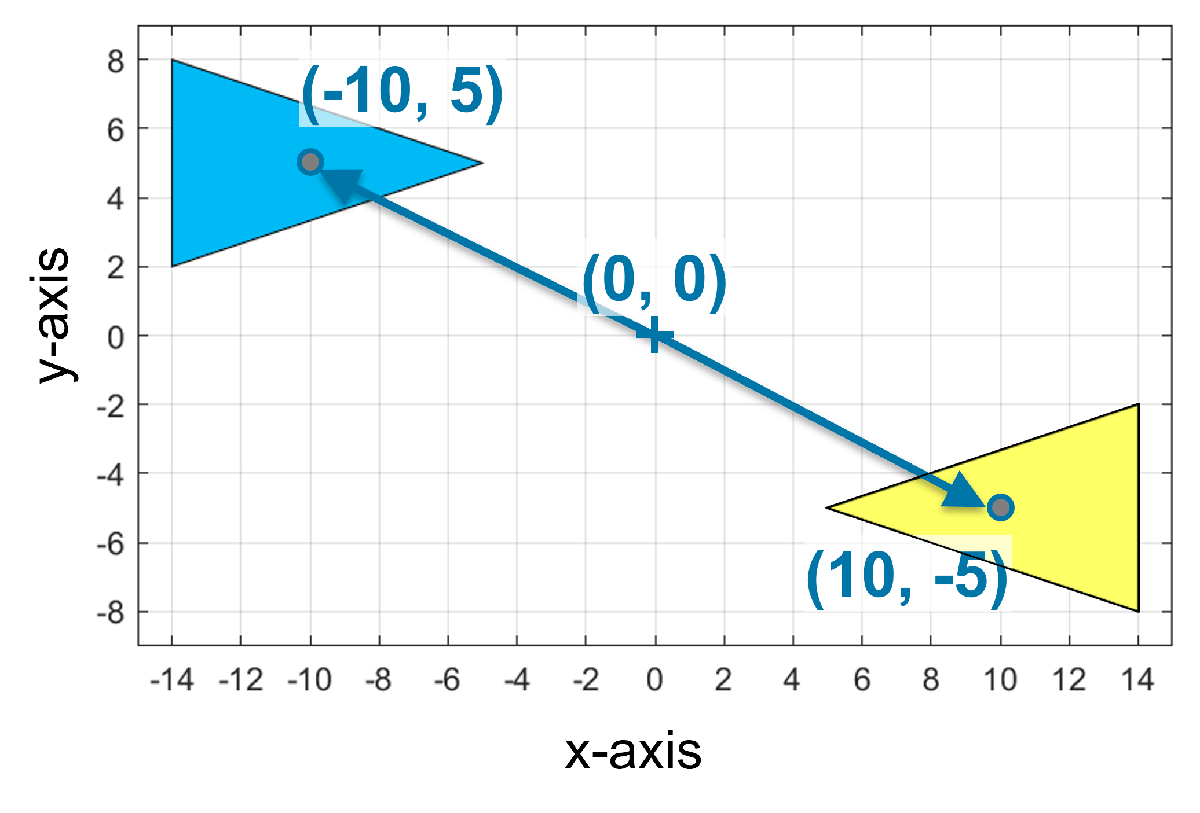

% TASK 7: All of the Ship 2 values have been set to 0 below. Replace
% these zeros with values that match the x-location, y-location,
% size, and approximate color of the yellow ship illustrated above.
xs = [-10 0];         % [ship1 ship2] x-position
ys = [  5 0];         % [ship1 ship2] y-position
Rs = [  5 0];         % [ship1 ship2] size
cs = [0 186 245; ...  % row 1: ship1 color code
      0   0   0]/255; % row 2: ship2 color code

As you've seen above, by default MATLAB does not keep the previous plot in the new plot figure.  In order to display both ships in the same figure, we'll need to command the axes to `hold` "on" to the previous plot.  The axes will then hold on to all future plots until commanded "off".

% Plot Ship 1 (negative to face right)
cla(ax)  % clear axes
fill(ax,xs(1)-Rs(1)*xt,ys(1)+Rs(1)*yt,cs(1,:))
hold(ax,"on")

% TASK 8: Plot Ship 2 by changing all of the 1 indices below to 2.
fill(ax,xs(1)+Rs(1)*xt,ys(1)+Rs(1)*yt,cs(1,:))

## Final Solution (No Tasks)

Finally, let's consolidate all of our code into one section below.  However, this time we'll spread out the locations of our spaceships like they will be in the game (app).  We can also turn "on" the `grid`.

ax = gca;  % get current axes
cla(ax)    % clear axes

% Spaceship Parameters
xs = [-225  225];     % ship x-positions
ys = [ 100 -100];     % ship y-positions
Rs = [   5    5];     % ship sizes
cs = [0 186 245; ...
    255 255 102]/255; % ship colors (normalized by 255)

% Points of a unit triangle
xt = [-5 4 4 -5]/5;   % triangle x-points
yt = [ 0 3 -3 0]/5;   % triangle y-points

% Plot Ship 1 (negative to face right)
fill(ax,xs(1)-Rs(1)*xt,ys(1)+Rs(1)*yt,cs(1,:))
hold(ax,"on")

% Plot Ship 2 (no negative to face left)
fill(ax,xs(2)+Rs(2)*xt,ys(2)+Rs(2)*yt,cs(2,:))
grid(ax,"on")

% Set display limits
xlim(ax,[-300 300])  % x-axis limits [min max]
ylim(ax,[-200 200])  % y-axis limits [min max]

Copyright 2022 The MathWorks, Inc.